# MATLAB Notes

## Vector indexing

v = [ 1, 3, 6, 9, 12]; % 1 x N --> row vector
v(2)

ans = 3

v(end)

ans = 12

v(end-2)

ans = 6

whos v 

  Name      Size            Bytes  Class     Attributes

  v         1x5                40  double              




colV = v'; % N x 1 --> column vector : same way to access
whos colV

  Name      Size            Bytes  Class     Attributes

  colV      5x1                40  double              



colV(2)

ans = 3

colV(end)

ans = 12

colV(end-2)

ans = 6


% access range of elements
v(1:3)

ans =      1     3     6


v(2:4)

ans =      3     6     9



% construct a column vector
wth = v(:) % : == all the elements,  same as used with matrix . note that this produces from row vector a column vector

wth =      1
     3
     6
     9
    12


wht2= colV(:) % when it already was a column, we get a column again

wht2 =      1
     3
     6
     9
    12



rowV = v(1:end) % results is row vector 

rowV =      1     3     6     9    12


wtf3= colV(1:end) % result is col vector

wtf3 =      1
     3
     6
     9
    12



%indexing is not restricted to consecutive elements
other = v(1:2:5)

other =      1     6    12


other2 = v(end:-2:1) % indexing backwards

other2 =     12     6     1


other3 = v(1:2:end)

other3 =      1     6    12



x = linspace(0,50,6) % generate row vector with 6 elements between 1 and 50 (the interval is divided in equal chunks) --> we say how many points we want, and the chunk size is determined

x =      0    10    20    30    40    50


x = 0:10:50 % similar effect - perhaps more naturally - we say the chunk size between the points

x =      0    10    20    30    40    50



% access with index array
v([1,5])

ans =      1    12


v(v > 3) % row vector

ans =      6     9    12


colV(colV > 3) % col vector

ans =      6
     9
    12


## Matrix indexing

## subscript indexing

% same principles as vectors
A = [ 1 2 3; 4 5 6];
A(1,1)

ans = 1

A(end, end)

ans = 6

A(A>1) % return a column vector

ans =      4
     2
     5
     3
     6


A(end, end) = 7

A =      1     2     3
     4     5     7


A(A > 6) = 6

A =      1     2     3
     4     5     6


% 
A(:,2) % : == all the elements

ans =      2
     5


A([1,2],2) % I can specify the elements manually in index, too

ans =      2
     5


A([1; 2],2) % it does not matter if I use in index column or row vector

ans =      2
     5



A(:) %all elements in the matrix

ans =      1
     4
     2
     5
     3
     6


sum(A(:)) % shorter than sum(sum(A))

ans = 21

sum(sum(A))

ans = 21

## linear indexing

Matlab stores matrices in column first order - we see this order when we do A(:). We can access matrix elements using this order.

A

A =      1     2     3
     4     5     6


A(6)

ans = 6

## Selecting array dimensions

sum(A,1)

ans =      5     7     9


sum(A,2) % same pattern for many operations, e.g. size(A, 2)

ans =      6
    15


## Retrieving number of dimensions: never returns less than 2

ndims(A)

ans = 2

ndims(v) % 1 x N

ans = 2

ndims(5) % note that scalars have 2 dimensions (1x1)

ans = 2

## Matrix creation

ones(5)

ans =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


ones (5,3)

ans =      1     1     1
     1     1     1
     1     1     1
     1     1     1
     1     1     1


zeros(3, 'uint8')

ans =     0    0    0
    0    0    0
    0    0    0


magic(5)

ans =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


uniform = rand(10) % uniform distribution, between 0 and 1, probability  is the same for close to 0 or close to 1

uniform =     0.6386    0.8994    0.5139    0.6893    0.8606    0.7186    0.2442    0.1241    0.4551    0.2591
    0.9199    0.8299    0.3552    0.7628    0.0564    0.8749    0.9403    0.5670    0.3085    0.4660
    0.7408    0.4850    0.4846    0.5523    0.8102    0.4265    0.3427    0.4728    0.7133    0.5758
    0.3787    0.2749    0.7112    0.0675    0.2743    0.4646    0.8690    0.2697    0.9081    0.8544
    0.3614    0.4646    0.8182    0.5749    0.0182    0.1341    0.9302    0.9839    0.4446    0.0287
    0.9267    0.7030    0.7375    0.1994    0.3544    0.0917    0.3375    0.2130    0.7745    0.7341
    0.4079    0.7630    0.9481    0.5182    0.6326    0.4818    0.2712    0.2500    0.5681    0.2314
    0.0161    0.9916    0.3511    0.9514    0.3620    0.9303    0.5261    0.9511    0.1055    0.7809
    0.0880    0.7198    0.6679    0.1183    0.5133    0.4471    0.5987    0.7431    0.4054    0.6782
    0.7059    0.4570    0.8882    0.9686    0.9987    0.3107    0.5646    0.5117 

normal = randn(10) % normal distibution, between -1 and 1, probability of something close to 0 is much higher than at the edges

normal =    -0.7473    0.0122    1.3833   -0.7140   -0.4276   -0.6211   -0.8860    0.1696    1.4087   -1.2150
    1.2748   -0.1933   -0.6571    0.6031    0.8151    1.3770    1.6341    0.4686    0.0955   -0.7195
    1.1329   -1.0714    0.3589    0.0617    0.8708   -1.3756    1.9018    0.0292   -1.8569   -0.2079
    1.2518   -0.2638   -2.2595    0.4510    0.7488   -0.9714    0.8209   -0.8326    0.3019    1.1287
   -0.4731    0.6950   -1.6225    0.4107   -1.2747   -0.1655    0.8360   -0.2836   -0.0748    1.4394
    0.6669   -0.4976    0.7122    0.1529    0.6815    0.6275    0.5031   -0.2843    0.4151    0.2072
   -0.0975    0.1747    0.5019    0.4496   -0.1006   -1.8526    0.5757   -0.8154    0.7515    0.4313
    0.5684   -2.5490    1.9684    0.5657    0.2007   -2.4546   -0.3223   -0.1615   -1.1248   -1.0426
    0.7923   -1.6753    1.7084    0.8252    0.7268    1.5665   -0.0058   -0.4638    2.0233    0.3288
    2.0925    0.4293   -1.0131   -1.0675    0.4328   -0.3250   -0.1267   -0.9862  

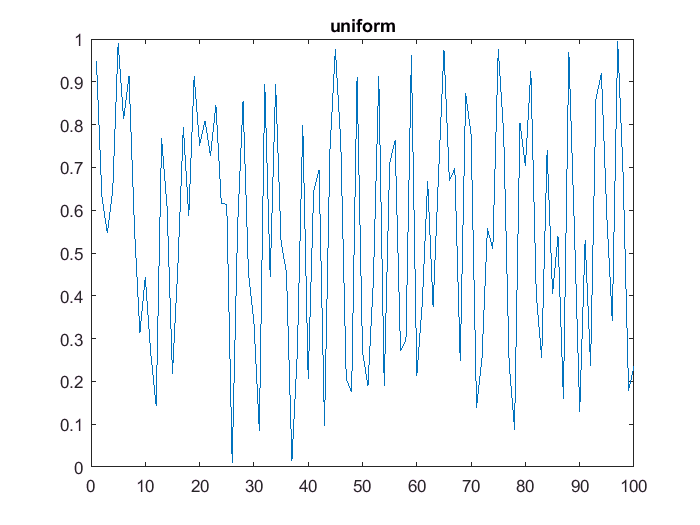

figure; plot(uniform(:)); title('uniform');

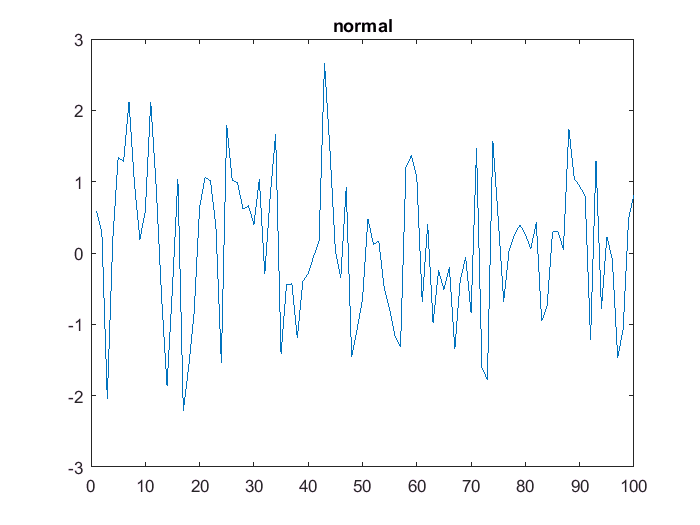

figure; plot(normal(:)); title('normal');

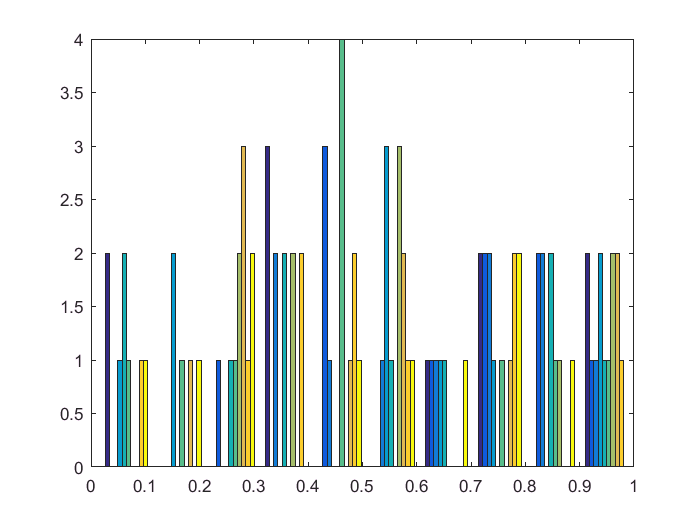

figure; hist(uniform);

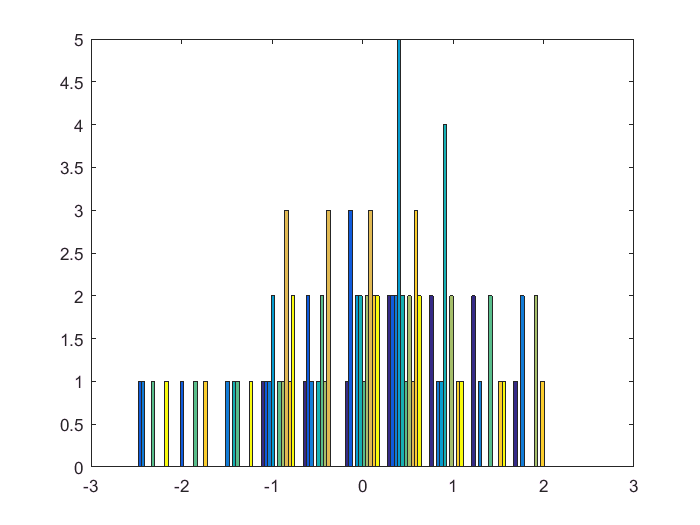

figure; hist(normal);

## Getting help

doc randn
lookfor normal

robNormFit                     - Parameter estimates and confidence intervals for normal data using rank statistics.
normalizeImageToReference      - Normalize an image so that the paper and ink intensity matches another image
normalizeImageToReferenceTest  - Tests for normalizeImageToReferenceTest
realmin                        - Smallest positive normalized floating point number.
randn                          - Normally distributed pseudorandom numbers.
sprandn                        - Sparse normally distributed random matrix.
surfnorm                       - Surface normals.
noanimate                      - Modify figure to make all objects have normal erasemode.
<a href

help randn

 randn Normally distributed pseudorandom numbers.
    R = randn(N) returns an N-by-N matrix containing pseudorandom values drawn
    from the standard normal distribution.  randn(M,N) or randn([M,N]) returns
    an M-by-N matrix. randn(M,N,P,...) or randn([M,N,P,...]) returns an
    M-by-N-by-P-by-... array. randn returns a scalar.  randn(SIZE(A)) returns
    an array the same size as A.
 
    Note: The size inputs M, N, P, ... should be nonnegative integers.
    Negative integers are treated as 0.
 
    R = randn(..., CLASSNAME) returns an array of normal values of the 
    specified class. CLASSNAME can be 'double' or 'single'.
 
    R = randn(..., 'like', Y) returns an array of normal values of the
    same class as Y.
 
    The sequence of numbers produced by randn is determined by the settings of


## Operators

Matrix and array (elementwise) operators

A = ones(3)

A =      1     1     1
     1     1     1
     1     1     1


B=  magic(3)

B =      8     1     6
     3     5     7
     4     9     2



A + B %note that there is no such thing as .+

ans =      9     2     7
     4     6     8
     5    10     3


A*B

ans =     15    15    15
    15    15    15
    15    15    15


A .* B

ans =      8     1     6
     3     5     7
     4     9     2
